# GLM

close all;clear;clc;
rng('default')
addpath models\
addpath utils\
load("data/data_rat010_0615_spike_train_selected.mat")

## Grid Search

Predict **7th** neuron

regulization parameter **alpha **almost useless, might be useful when **xi **is lare and **alpha **is quite small(0~0.1). Use 0 first.

H larger likely be better. xi need not explore a lot.

GLM_explore_H = struct( ...
  "H",{}, "xi",{}, "thres",{}, "iterThres",{}, ...
  "maxIter",{}, "alpha",{}, "M1Idx",{}, ...
  "W",{}, "L",{}, "DBR",{}, "Lval",{}, "LHistory",{} ...
  );
for H=1:10 % Temporal history. Explore within [1:10]
  xi=0.1; % Weights random initial range parameter
  alpha=0; % Regulization parameter
  thres = 1e-3; % stop error tolerance
  iterThres = 7; % stop after error over threshold $ times
  maxIter = 40; % max iteration num, over needs re-initial
  M1Idx = 2; % select M1 neuron
  splitFun = @(history)splitData(mPFCspike,M1spike(:,M1Idx),history); % choose splitData function as first Order
  verbose = 3;
  [W, L, DBR, Lval, LHistory] = runGLM(H, xi, thres, iterThres, maxIter, alpha, splitFun, verbose);
  GLM_explore_H(H) = struct( ...
    "H",H, "xi",xi, "thres",thres, "iterThres",iterThres, ...
    "maxIter",maxIter, "alpha",alpha, "M1Idx",M1Idx, ...
    "W",W, "L",L, "DBR",DBR, "Lval",Lval, "LHistory",LHistory ...
    );
  disp(['H ', num2str(H), ' xi ', num2str(xi), ' DBR ', num2str(DBR)])
end

H 1 xi 0.1 i 0+1i DBR 1.1297
H 2 xi 0.1 i 0+1i DBR 1.1139
H 3 xi 0.1 i 0+1i DBR 1.0968
H 4 xi 0.1 i 0+1i DBR 1.0918
H 5 xi 0.1 i 0+1i DBR 1.0832
H 6 xi 0.1 i 0+1i DBR 1.0882
H 7 xi 0.1 i 0+1i DBR 1.0858
H 8 xi 0.1 i 0+1i DBR 1.093
H 9 xi 0.1 i 0+1i DBR 1.0945
H 10 xi 0.1 i 0+1i DBR 1.0901


% save("results\GLM_explore_H.mat", "GLM_explore_H")

## Result analyze

### DBR-history

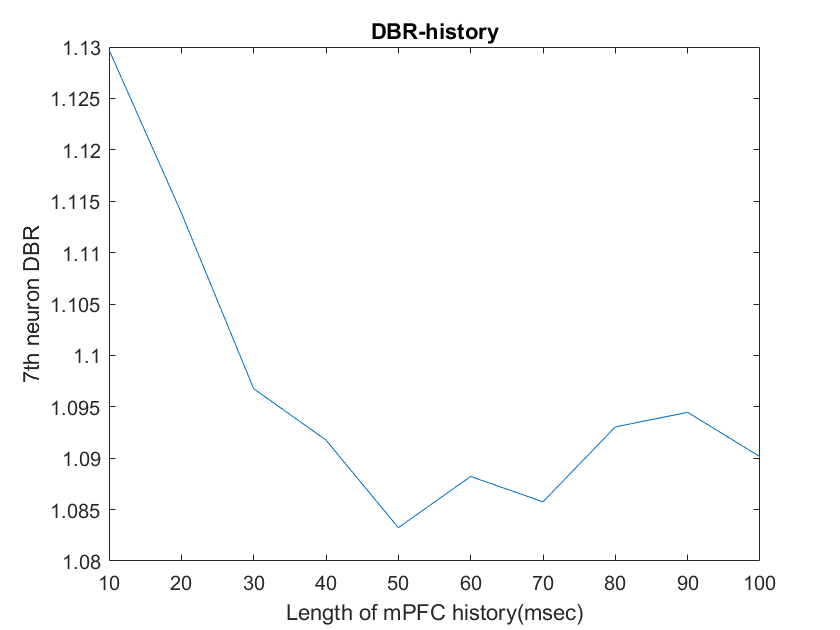

DBR = zeros(1,10);
for i=1:10
  DBR(i) = GLM_explore_H(i).DBR;
end
figure(1)
plot(10:10:100, DBR)
xlabel("Length of mPFC history(msec)")
xlim([10 100])
ylabel("7th neuron DBR")
title("DBR-history")

### firing rate, cc kernel size analyze

Take history=9 for firing rate cc-kernel size analyze, kernel size changes from 10~1000(*10msec)

W = GLM_explore_H(5).W;
H = GLM_explore_H(5).H;
M1Idx = GLM_explore_H(5).M1Idx;
[~,~,testLen,~,~,testX,~,~,testY] = splitData(mPFCspike,M1spike(:,M1Idx),H);
testLambdaYpre = GLMmodel(testX, W);
ccList = zeros(1, 1000/10);
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(testLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ccList(kernelSize/10) = cc(2);
end

take kernel size=200(2s) for plot

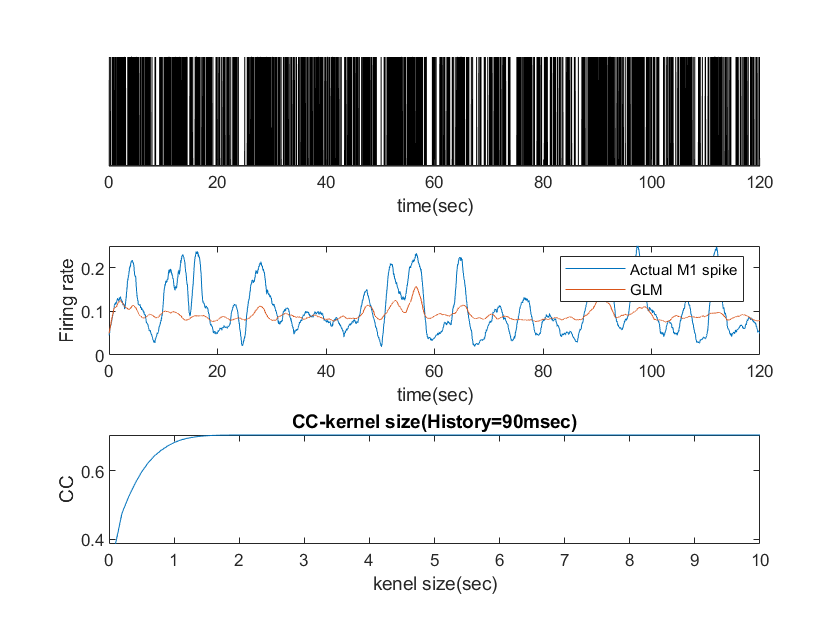

smoothedLambda    = gaussianSmooth(testY, 100);
smoothedLambdaPre = gaussianSmooth(testLambdaYpre, 100);
figure(2)
subplot(3,1,1)
area(0.01:0.01:120, testY(1:12000))
xlabel("time(sec)")
set(gca, 'ytick', [])
set(gca, 'box', 'off')
subplot(3,1,2)
plot(0.01:0.01:120, smoothedLambda(1:12000))
hold on
plot(0.01:0.01:120, smoothedLambdaPre(1:12000))
hold off
xlabel("time(sec)")
ylabel("Firing rate")
legend("Actual M1 spike", "GLM")
subplot(3,1,3)
plot(0.1:0.1:10, ccList)
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size(History=90msec)")